%% Controle Preditivo - Aline
% Codigo Oinf comparativo 
%-----------------------------------
clc; clear; close all;


## Parametros

% ddtheta = -b*dtheta-a*sin(theta)+c*w^2
% w = sqrt((a*sen(theta)+u)/c) -> ddtheta = -b*dtheta+u
%----------------------------------------------------
% Parametros do aeropendulo
a = 3.547623e+01; b = 8.695879e-01; c = 1.097177e-06;

Ac = [0 1; 0 -b];
Bc = [0;1];
C = [1 0];
Ec = [0;1];
T = 0.1;

% Dimencoes da planta
nx = length(Ac);
nu = size(Bc,2);
nq = size(C,1);
nd = size(Ec,2);

Td_smc = 0.1; % Tempo de amostragem da planta
N = 40; % Horizonte de predicao

% Matrizes de Peso
q = 120; % Ajustado via LQR - LGR
Q = q*C'*C;
R = 1;

%% Discretizacao
[A, B] = c2dm(Ac,Bc,[],[],T, 'zoh');

% LQR
[K,P] = dlqr(A,B,Q,R);
Af = A-B*K;

%% Ponto de equilibrio
aux = inv([A - eye(2) B;C 0])*[0;0;1];
Nx = aux(1:2);
Nu = aux(3);

%% Restricoes Sxu *[x;u] <= bxu ; Sxu *[xbar;ubar] <= bxu
umax = 20;
umin = 0;

Sxu = [1 0 0; -1 0 0; a 0 1; -2*a/pi 0 -1];
bxu = [pi/2; 0; umax; -umin];
exu = 1e-3*ones(size(Sxu,1),1);

%% Restrições: Sx*x <= bx
Sx = Sxu(1:nx,1:nx); 
bx = bxu(1:nx);
ex = 1e-3*ones(size(bx,1),1);

max_iter = 100; tol = 1e-6;

rbar = 0;
xbar = Nx*rbar; ubar = Nu*rbar;

## Determinar O_inf : rbar = 0 fixo

Gamma_fixo = [eye(nx);-K];

Spsi_fixo = Sxu;
bpsi_fixo = bxu;

[Sf_fixo,bf_fixo,Si,bi] = Oinf_MAS(Af,Gamma_fixo,Spsi_fixo,bpsi_fixo,max_iter,tol);

Iteração 1 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 2 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 3 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 4 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 5 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 6 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 7 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 8 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 9 / 100

Optimal soluti

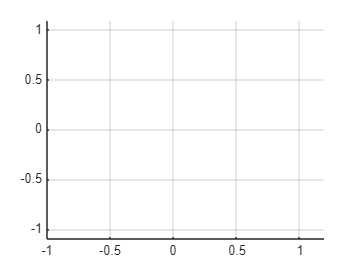

bf_fixo = bf_fixo + Sf_fixo*xbar;

Oinf_fixo = Polyhedron('H',[Sf_fixo bf_fixo]); % Declaração de Oinf como objeto do MPT Toolbox
plot(Oinf_fixo)

## Determinar O_psi_inf - todas as refs

Achif = [Af B*(K*Nx + Nu);
        zeros(nq,nx) eye(nq)];

Gamma_rbar = [eye(nx) zeros(nx,nq);
        -K (K*Nx + Nu);
        zeros(nx,nx) Nx;
        zeros(nu,nx) Nu];

Spsi_rbar = blkdiag(Sxu,Sxu);
bpsi_rbar = [bxu;bxu-exu];


[So,bo] = Oinf_MAS(Achif,Gamma_rbar,Spsi_rbar,bpsi_rbar,max_iter,tol);

Iteração 1 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 2 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 3 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 4 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 5 / 100

Optimal solution found.


Optimal solution found.


Optimal solution found.


Opti

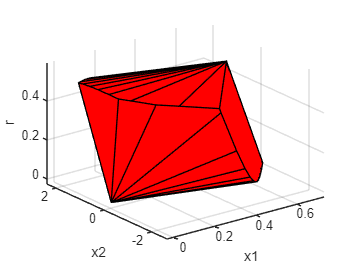


Ochi_inf = Polyhedron('H',[So bo]);
plot(Ochi_inf); xlabel('x1'); ylabel('x2'); zlabel('r')

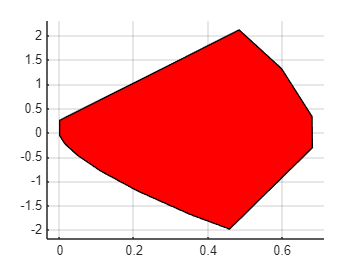


% Particionando pra rbar ;
Ox = So(:,1:nx);
Or = So(:,nx+1:end);

Sf_rbar = Ox;
bf_rbar = bo - Or*rbar;

Oinf_rbar = Polyhedron('H',[Sf_rbar bf_rbar]);

plot(Oinf_rbar)


% Referencias admissiveis
x0 = [0.2;0];
br = bo - Ox*x0;
index = find(Or == 0);
index_p = find(Or > 0);
index_n = find(Or < 0);
rbarra_max = min(br(index_p)./Or(index_p))

rbarra_max = 0.5528

rbarra_min = max(br(index_n)./Or(index_n))

rbarra_min = 0.0075


% Comparar se os conjuntos sao iguais
teste1 = Oinf_fixo.contains(Oinf_rbar)

teste1 = logical
   0


teste2 = Oinf_rbar.contains(Oinf_fixo)

teste2 = logical
   1
